clear; clc;

Seção inicial: definições do experimento para 4-QAM (QPSK)

% ranges de simulação
EbN0dB = 0:1:20;
EbN0 = 10.^(EbN0dB/10);
% Número de bits testados por amostra
Ns = 1e6;

% Vetores auxiliares para guardar os resultados
Pb = zeros(2, numel(EbN0dB)); % Probabilidade de erro (teórica)
BER = Pb; % Taxa de erro de bits (simulada)

item a: Mapeamento Natural

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    bits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    I = 2*bits(1:2:end)-1; % [-1 +1]
    Q = 2*bits(2:2:end)-1; % [-1 +1]

    s = I + 1j*Q; % sinal
    n = sigma*(randn(Ns,1) + 1j*randn(Ns,1)); % noise
    r = s + n;

    % calculando resultados
    BER(1, ii) = mean((sign(real(r))~=I) | (sign(imag(r))~=Q));
    q = qfunc(sqrt(2*EbN0(ii)));
    Pb(1, ii) = 2*q - q.^2;
end

item b: Mapeamento Gray

for ii = 1:numel(EbN0)
    N0 = 1./EbN0(ii); % considerando Eb = 1
    sigma = sqrt(N0/2);
    
    % rodando o experimento
    bits = randi([0 1], 2*Ns, 1); % geram-se 2*Ns bits
    I = 2*bits(1:2:end)-1; % [-1 +1]
    Q = 2*bits(2:2:end)-1; % [-1 +1]

    s = I + 1j*Q; % sinal
    n = sigma*(randn(Ns,1) + 1j*randn(Ns,1)); % noise
    r = s + n;

    % calculando resultados
    BER(2, ii) = mean((sign(real(r))~=I) | (sign(imag(r))~=Q));
    q = qfunc(sqrt(2*EbN0(ii)));
    Pb(2, ii) = 2*q - q.^2;
end

Seção final: Plotando os gráficos:

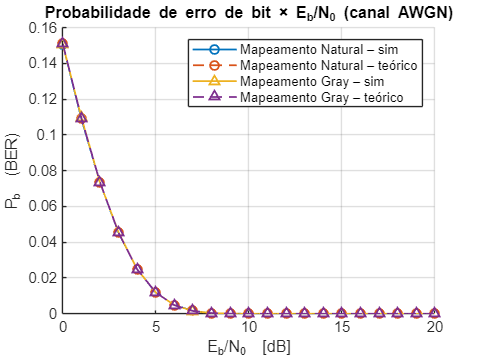

figure; hold on; grid on;
mods   = {'Mapeamento Natural','Mapeamento Gray'};
marks  = {'o','^'};

for m = 1:2
    semilogy(EbN0dB,BER(m,:),['-' marks{m}],'LineWidth',1.2);
    semilogy(EbN0dB,Pb (m,:),['--' marks{m}],'LineWidth',1.2);
end

xlabel('E_b/N_0  [dB]'); ylabel('P_b  (BER)');
legend( [strcat(mods,' – sim').', strcat(mods,' – teórico').'].', ...
    'Location','northeast');
title('Probabilidade de erro de bit × E_b/N_0 (canal AWGN)');